# Pascal Triangle MLP

Combinatorics and Fibonacci can be derived. Constants such as e, natural numbers and common fractions can be derived. We can look at Bernoulli's triangle too for cake numbers and dividing circles amongst a myriad of other useful number patterns.

pascal(10)

ans =            1           1           1           1           1           1           1           1           1           1
           1           2           3           4           5           6           7           8           9          10
           1           3           6          10          15          21          28          36          45          55
           1           4          10          20          35          56          84         120         165         220
           1           5          15          35          70         126         210         330         495         715
           1           6          21          56         126         252         462         792        1287        2002
           1           7          28          84         210         462         924        1716        3003        5005
           1           8          36         120         330         792        1716        3432        6435       11440
           1           9  

levels = 10;
first = fullyConnectedLayer(1,'Bias',zeros(1,1),'Weights',ones(1,1),'Name','unit11');

layers = [imageInputLayer([1 1 1],'Name','in','Normalization',"none")
    first]

layers =   2×1 Layer array with layers:

     1   'in'       Image Input       1×1×1 images
     2   'unit11'   Fully Connected   1 fully connected layer

lgraph = layerGraph(layers)

lgraph =   LayerGraph with properties:

         Layers: [2×1 nnet.cnn.layer.Layer]
    Connections: [1×2 table]
     InputNames: {'in'}
    OutputNames: {1×0 cell}


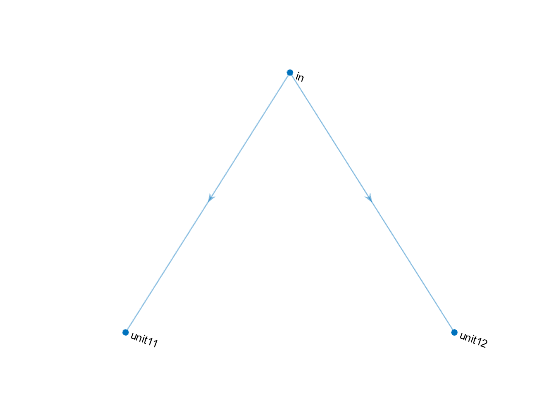

nextlayer = fullyConnectedLayer(1,'Bias',zeros(1,1),'Weights',ones(1,1),'Name','unit12');

lgraph = addLayers(lgraph,nextlayer);
lgraph = connectLayers(lgraph,'in','unit12');

plot(lgraph);
axis off

for i = 2:levels
    for j = 1:i+1
        lgraph = branchme(lgraph,i,j);
    end
end

nnet_cnn:nnet:cnn:LayerGraph:LayerDoesNotExist
Edge of the triangle! Connects to 0, unit10
nnet_cnn:nnet:cnn:LayerGraph:LayerDoesNotExist
Edge of the triangle! Connects to 0, unit13
nnet_cnn:nnet:cnn:LayerGraph:LayerDoesNotExist
Edge of the triangle! Connects to 0, unit20
nnet_cnn:nnet:cnn:LayerGraph:LayerDoesNotExist
Edge of the triangle! Connects to 0, unit24
nnet_cnn:nnet:cnn:LayerGraph:LayerDoesNotExist
Edge of the triangle! Connects to 0, unit30
nnet_cnn:nnet:cnn:LayerGraph:LayerDoesNotExist
Edge of the triangle! Connects to 0, unit35
nnet_cnn:nnet:cnn:LayerGraph:LayerDoesNotExist
Edge of the triangle! Connects to 0, unit40
nnet_cnn:nnet:cnn:LayerGraph:LayerDoesNotExist
Edge of the triangle! Connects to 0, unit46
nnet_cnn:nnet:cnn:LayerGraph:LayerDoesNotExist
Edge of the triangle! Connects to 0, unit50
nnet_cnn:nnet:cnn:LayerGraph:LayerDoesNotExist
Edge of the triangle! Connects to 0, unit57
nnet_cnn:nnet:cnn:LayerGraph:LayerDoesNotExist
Edge of the triangle! Connects to 0, unit60

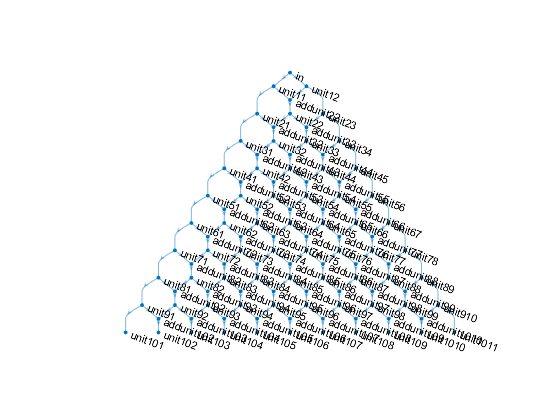

plot(lgraph);
axis off

outs = [depthConcatenationLayer(levels+1,'Name','output_prep');regressionLayer("Name","rmse")];

lgraph = addLayers(lgraph,outs);
for i = 1:levels+1
lgraph = connectLayers(lgraph,"unit"+int2str(levels)+int2str(i),"output_prep/in"+int2str(i));
end

pascal_triangle = assembleNetwork(lgraph)

pascal_triangle =   DAGNetwork with properties:

         Layers: [113×1 nnet.cnn.layer.Layer]
    Connections: [167×2 table]
     InputNames: {'in'}
    OutputNames: {'rmse'}


predict(pascal_triangle,[1])

ans = 1×11 single row vector
     1    10    45   120   210   252   210   120    45    10     1


function lgraph = branchme(lgraph,x,y)
name = "unit"+int2str(x)+int2str(y);
con1 = "unit"+int2str(x-1)+int2str(y-1); con2 = "unit"+int2str(x-1)+int2str(y);
if y == 1 || y == x+1
    nextlayer = fullyConnectedLayer(1,'Bias',zeros(1,1),'Weights',ones(1),'Name',name);
    lgraph = addLayers(lgraph,nextlayer);
    try
        lgraph = connectLayers(lgraph,con1,name);
    catch ME
        disp(ME.identifier)
        disp("Edge of the triangle! Connects to 0, " + "unit"+int2str(x-1)+int2str(y-1))
    end
    try
        lgraph = connectLayers(lgraph,con2,name);
    catch ME
        disp(ME.identifier)
        disp("Edge of the triangle! Connects to 0, " + "unit"+int2str(x-1)+int2str(y))
    end
else
    nextlayer = [depthConcatenationLayer(2,'Name',"add"+name);fullyConnectedLayer(1,'Bias',zeros(1,1),'Weights',ones(1,2),'Name',name)];
    lgraph = addLayers(lgraph,nextlayer);
    try
        lgraph = connectLayers(lgraph,con1,"add"+name+"/in1");
    catch ME
        disp(ME.identifier)
        disp("Edge of the triangle! Connects to 0, " + "unit"+int2str(x-1)+int2str(y-1))
    end
    try
        lgraph = connectLayers(lgraph,con2,"add"+name+"/in2");
    catch ME
        disp(ME.identifier)
        disp("Edge of the triangle! Connects to 0, " + "unit"+int2str(x-1)+int2str(y))
    end
end

end